# Algortimos genéticos (Toolbox)

Optimization terminated: maximum number of generations exceeded.


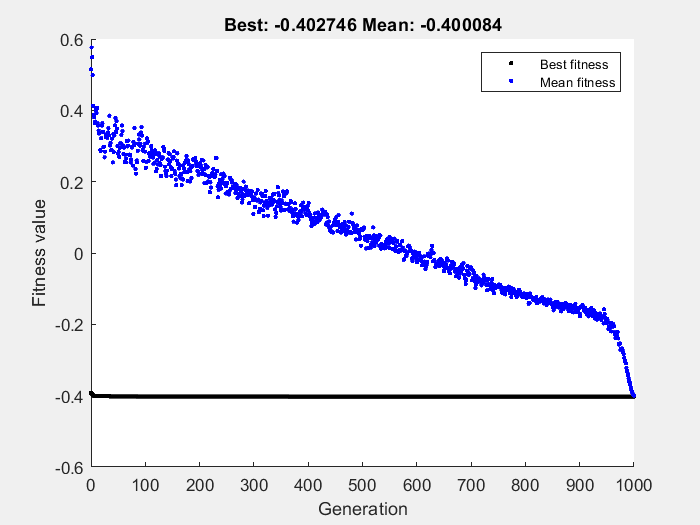

solution0 =     1.2508   -1.5084


objectiveValue0 = -0.4027

%help ga 

clear;

rng shuffle; %semilla aleatoria 

liminf=[2 2 2 2 2 2 2 2 2 2];
limsup=[10 10 10 10 10 10 10 10 10 10];

options=optimoptions('ga', 'PlotFcn','gaplotbestf', ... %Recocido simuldo (Se plotea el mejor)
    'MaxGenerations', 1000, ...
    'MaxStallGenerations', 500, ...
    'PopulationSize', 1000, ...
    'FunctionTolerance', 1E-8, ...
    'UseVectorized',false);

[solution0, objectiveValue0]=ga(@f2v,10,[],[],[],[],[],[],[],options) %[x, f(x)] %2: Número de variables

solution0 

solution0 =     1.2508   -1.5084


f2v(solution0)

ans = -0.4027

function f= f2v(x) %Se vectoriza la función 
    f=besselj(0,x(:,1).^2+x(:,2).^2)+.1.*abs(1-x(:,1)+.1.*abs(1-x(:,2)));
%     f= 100.*(x(:, 2) - x(:, 1).^2).^2 + (1 - x(: ,1)).^2 + 100.*(x(: ,3) - x(: ,2).^2).^2 + (1 - x(:, 2)).^2 + ...
% 100.*(x(:, 3) - x(: ,2).^2).^2 + (1 - x(: ,2)).^2 + 100.*(x(: ,4) - x(: ,3).^2).^2 + (1 - x(: ,3)).^2 + 100.*(x(:, 5) - x(:, 4).^2).^2 + (1 - x(:, 4)).^2 ... 
%  + 100.*(x(: ,6) - x(: ,5).^2).^2 + (1 - x(: ,5)).^2 + 100.*(x(: ,7) - x(: ,6).^2).^2 + (1 - x(: ,6)).^2; 
f=(log((x(:,1))-2)).^2+(log(10-x(:,1))).^2+(log(x(:,2)-2)).^2+(log(10-x(:,2))).^2+(log(x(:,3)-2)).^2+(log(10-x(:,3))).^2+(log(x(:,4)-2)).^2+(log(10-x(:,4))).^2+(log(x(:,5)-2)).^2+(log(10-x(:,5))).^2 ...
    +(log(x(:,6)-2)).^2+(log(10-x(:,6))).^2+(log(x(:,7)-2)).^2+(log(10-x(:,7))).^2+(log(x(:,8)-2)).^2+(log(10-x(:,8))).^2+(log(x(:,9)-2)).^2+(log(10-x(:,9))).^2+(log(x(:,10)-2)).^2+(log(10-x(:,10))).^2 ...
    -x(:,1).*x(:,2).*x(:,3).*x(:,4).*x(:,5).*x(:,6).*x(:,7).*x(:,8).*x(:,9).*x(:,10);
end